#  Levelized Cost of Energy (LCOE) Analysis

## Introduction

This Live Script calculates and analyzes the Levelized Cost of Energy (LCOE) for different energy sources, including offshore wind, hydropower, and nuclear. The script also investigates the influence of CAPEX, OPEX, inflation, and Monte Carlo simulations.

The Levelized Cost of Energy (LCOE) is a key metric used to compare different energy generation technologies. It is defined as the total discounted cost of building and operating an energy generation facility divided by the total discounted energy produced over its lifetime.

The formula for LCOE is:


$$LCOE = \frac{\sum \frac{C_t}{(1+r)^t}}{\sum \frac{E_t}{(1+r)^t}} $$


where: $C_t$ = cost in year t (CAPEX, OPEX, Fuel costs, etc.); $E_t$ = energy production in year t; r = real discount rate, t = year index and n = project lifetime

The LCOE formula can be simplified as $\text{LCOE} = \frac{I \cdot \text{CRF} + O + F}{E}$

where I is the Initial capital expenditure (CAPEX), O is the Annual operational and maintenance costs (OPEX), F is the Annual fuel costs, E is the Annual energy production and Capital Recovery Factor, defined as:


$$\text{CRF} = \frac{r (1 + r)^n}{(1 + r)^n - 1}$$


whre *r *is the discount rate and n the Project lifetime (years). The discount rate can be nominal ($r_{nominal}$) or real  ($ r_{real}$ adjusted for inflation):


$$r_{\text{real}} = \frac{1 + r_{\text{nominal}}}{1 + i} - 1$$


where *i *is the inflation rate.

## Example 1: Test of an Offshore Wind Farm

Data source: [https://guidetoanoffshorewindfarm.com/wind-farm-costs](https://guidetoanoffshorewindfarm.com/wind-farm-costs) 

%% Clear Workspace and Set Up Environment
clearvars; close all; clc;

CAPEX = 2.37e6; % in €/MW
OPEX = 76000; % in €/MW/year
r_nominal = 0.06; % nominal discount rate (not corrected for inflation)
N = 27; % lifespan
Fuel = 0; % no fuel for wind farms
E = 4471; % MWh/year/MW
ir = 0; % inflation rate

lcoe = calculateLCOE_switch(CAPEX, OPEX, Fuel, E, r_nominal, ir, N);
fprintf('LCOE without inflation is %2.0f €/MWh \n', lcoe);

LCOE without inflation is 57 €/MWh 


## Example 2:  Influence of CAPEX, OPEX and inflation rate on LCOE Over Time

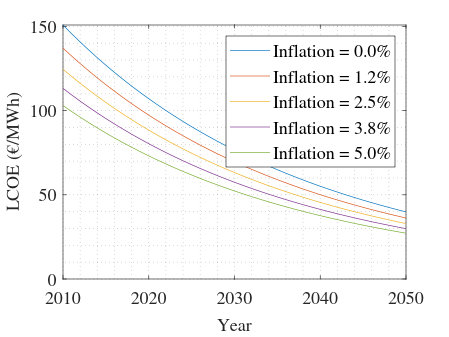

year = 2010:1:2050;
r_nominal = 0.06;
% Assume CAPEX decreases by 2.5% per year
CAPEX = 5000 * (1 - 0.025).^(year - 2010); % $/kW

% Assume OPEX is 3% of CAPEX per year
OPEX = 0.03 * CAPEX; % $/kW
Fuel = 0;
CF = linspace(0.4, 0.55, numel(year)); % Increasing CF over time
E = 8760 * CF; % Energy production per MW
N = 27;

ir = linspace(0, 0.05, 5); % Inflation rate scenarios
lcoe = zeros(numel(year), numel(ir));

for jj = 1:numel(ir)
    for ii = 1:numel(year)
        lcoe(ii, jj) = calculateLCOE_switch(CAPEX(ii), OPEX(ii), Fuel, E(ii), r_nominal, ir(jj), N);
    end
end

% Plot LCOE trend
figure;
plot(year, lcoe * 1000);
xlabel('Year');
ylabel('LCOE (€/MWh)');
grid minor;
legend(arrayfun(@(x) sprintf('Inflation = %.1f%%', x*100), ir, 'UniformOutput', false));
set(gcf, 'color', 'w');
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 14, 'FontName', 'Times');

## Example 3: LCOE Calculation for a Hydropower Plant

Source: [https://tbccapital.ge/static/file/202306214500-bag-tbc-capital-levelized-cost-of-electricity-report-jun-2023.pdf](https://tbccapital.ge/static/file/202306214500-bag-tbc-capital-levelized-cost-of-electricity-report-jun-2023.pdf)

capacity = 140; % MW
% Simplified equation
CAPEX = 500*1e6/capacity; % in €/MW
OPEX = 120*1e6/30/capacity; % in €/MW/year
r_nominal = 0.12; % nominal discount rate (not corrected for inflation) 
ir = 0.00; % inflation rate
N= 33; % lifespan
Fuel = 0; % no fuel for a wind farm
E = 16.5*1e6/N/capacity; % MWh/year/MW
lcoe = calculateLCOE_switch(CAPEX, OPEX, Fuel, E, r_nominal, ir, N);
fprintf('LCOE of hydroPower plant is %2.0f $/MWh \n',lcoe);

LCOE of hydroPower plant is 131 $/MWh 



% Full equation (it should be 135$/MWh as in the pdf)
T = readtable('hydropower_lcoe.csv','VariableNamingRule','modify');
N = numel(T.Year);
lcoe = calculateLCOE_switch(T.CAPEX_millionUSD*1e6/capacity, T.OPEX_millionUSD*1e6/capacity,zeros(N,1), T.Output_Twh*1e6/capacity, T.discountRate, zeros(N,1), N);
fprintf('LCOE of hydroPower plant is %2.0f $/MWh \n',lcoe);

LCOE of hydroPower plant is 135 $/MWh 


## Example 4: Monte Carlo Simulation for LCOE Uncertainty Analysis

Data Source: [https://www.lazard.com/media/xemfey0k/lazards-lcoeplus-june-2024-_vf.pdf](https://www.lazard.com/media/xemfey0k/lazards-lcoeplus-june-2024-_vf.pdf)

No data were available for a hydropower plant. We use uniform distribution for the selection of dtaapoints between the min-max intervals.

I have some small deviation from the report from lazard, but these are relatively minor 8except for the nuclear power plant; I may have done an error for the fuel cost)

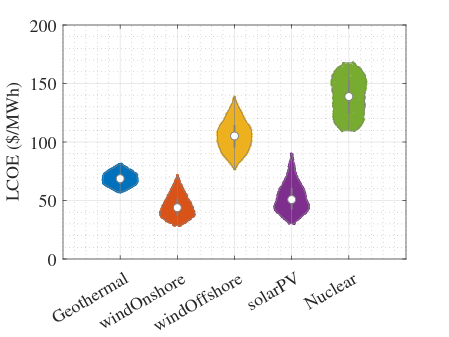

N_iter = 2000; % Number of Monte Carlo simulations
r_nominal = 0.07;
ir = 0.00;
% Geothermal
INPUT.Geothermal.CAPEX = [4860000,6280000]; % $/MW (converted from $1,300–$1,900 per kW)
INPUT.Geothermal.OPEX  = [24500,40000];      % $/MW/year (converted from $24.50–$40.00 per kW/year)
INPUT.Geothermal.CF    = [0.80,0.90];         % Capacity Factor (decimal)
INPUT.Geothermal.N     = 25;                   % Lifespan in years
INPUT.Geothermal.Fuel  = 0;                    % $/MMBTU
% Wind Onshore
INPUT.windOnshore.CAPEX = [1300000, 1900000]; % $/MW (converted from $1,300–$1,900 per kW)
INPUT.windOnshore.OPEX  = [24500, 40000];      % $/MW/year (converted from $24.50–$40.00 per kW/year)
INPUT.windOnshore.CF    = [0.30, 0.55];         % Capacity Factor (decimal)
INPUT.windOnshore.N     = 30;                   % Lifespan in years
INPUT.windOnshore.Fuel  = 0;                    % $/MMBTU
% Wind Offshore
INPUT.windOffshore.CAPEX = [3750000, 5750000];   % $/MW (converted from $3,750–$5,750 per kW)
INPUT.windOffshore.OPEX  = [60000, 91500];        % $/MW/year (converted from $60.00–$91.50 per kW/year)
INPUT.windOffshore.CF    = [0.45, 0.55];           % Capacity Factor (decimal)
INPUT.windOffshore.N     = 30;                   % Lifespan in years
INPUT.windOffshore.Fuel  = 0;                    % $/MMBTU
% Solar PV
INPUT.solarPV.CAPEX = [850000, 1400000];          % $/MW (converted from $850–$1,400 per kW)
INPUT.solarPV.OPEX  = [11000, 14000];             % $/MW/year (converted from $11.00–$14.00 per kW/year)
INPUT.solarPV.CF    = [0.15, 0.30];               % Capacity Factor (decimal)
INPUT.solarPV.N     = 35;                         % Lifespan in years
INPUT.solarPV.Fuel  = 0;                          % $/MMBTU
% Nuclear
INPUT.Nuclear.CAPEX = [8765000, 14400000];        % $/MW (converted from $8,765–$14,400 per kW)
INPUT.Nuclear.OPEX  = [140000, 163000];           % $/MW/year (converted from $140.00–$163.00 per kW/year)
INPUT.Nuclear.CF    = [0.89, 0.92];               % Capacity Factor (decimal)
INPUT.Nuclear.N     = 40;                         % Lifespan in years
INPUT.Nuclear.Fuel  = 8.88;                       % $/MWh

% List of technologies to simulate
techList = {'Geothermal','windOnshore','windOffshore','solarPV','Nuclear'};
nTech = numel(techList);

%% Monte Carlo Simulation Loop
for t = 1:nTech
    tech = techList{t};
    
    % Extract parameters for the current technology
    capex_range = INPUT.(tech).CAPEX;
    opex_range = INPUT.(tech).OPEX;
    cf_range   = INPUT.(tech).CF;
    lifespan   = INPUT.(tech).N;
    fuel_cost  = INPUT.(tech).Fuel;
    
    for ii = 1:N_iter
        % Sample uniformly for CAPEX, OPEX, and Capacity Factor
        CAPEX_sample = unifrnd(capex_range(1), capex_range(2));
        OPEX_sample  = unifrnd(opex_range(1), opex_range(2));
        CF_sample    = unifrnd(cf_range(1), cf_range(2));
        
        % Compute annual energy production (MWh/year per MW)
        % Assuming 8760 hours per year.
        E_sample = 8760 * CF_sample; % MWh/MW
        FUEL = fuel_cost*E_sample; % to convert into $/MW only

        % Calculate LCOE using the provided function (discounting costs over lifespan)
        lcoe_val = calculateLCOE_switch(CAPEX_sample, OPEX_sample, FUEL, E_sample, r_nominal, ir, lifespan);
        
        % Store the LCOE value (units: €/MWh)
        LCOE_sim(ii, t) = lcoe_val;
    end
end

figure
violinplot(LCOE_sim, techList,'MarkerSize',5);
ylabel('LCOE ($/MWh)');
grid on;
ylim([0 200]);
set(gcf, 'color', 'w');
grid minor
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')